# Exercise 7: Capture and Draw Live Images

## Connect to webcam

Identify webcams connected to your system. Connect to the first one in the list. If there are multiple webcams on your computer, specify the desired camera by the device number or camera name. You can use the camera provided in the kit or any other webcam you have access to.

webcamlist

ans = 2×1 cell array
    {'HP Wide Vision HD Camera'}
    {'HUE HD Pro Camera'       }


## Select the Webcam

% w = webcam;
w = webcam('HUE HD Pro Camera'); %Alternative syntax

## Preview webcam image

Preview live video data from the webcam.

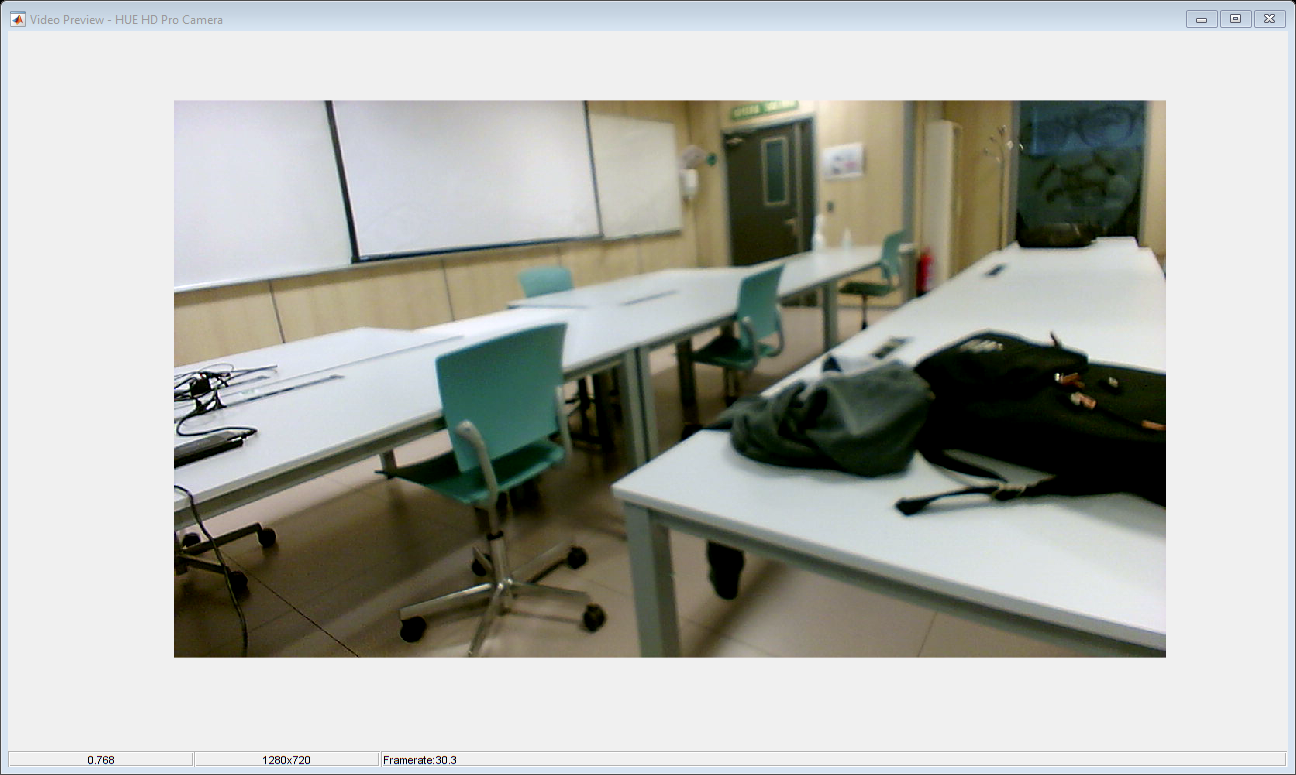

preview(w)

## Capture the current image

Use the `snapshot` command to capture the current image. Visualize the captured image.

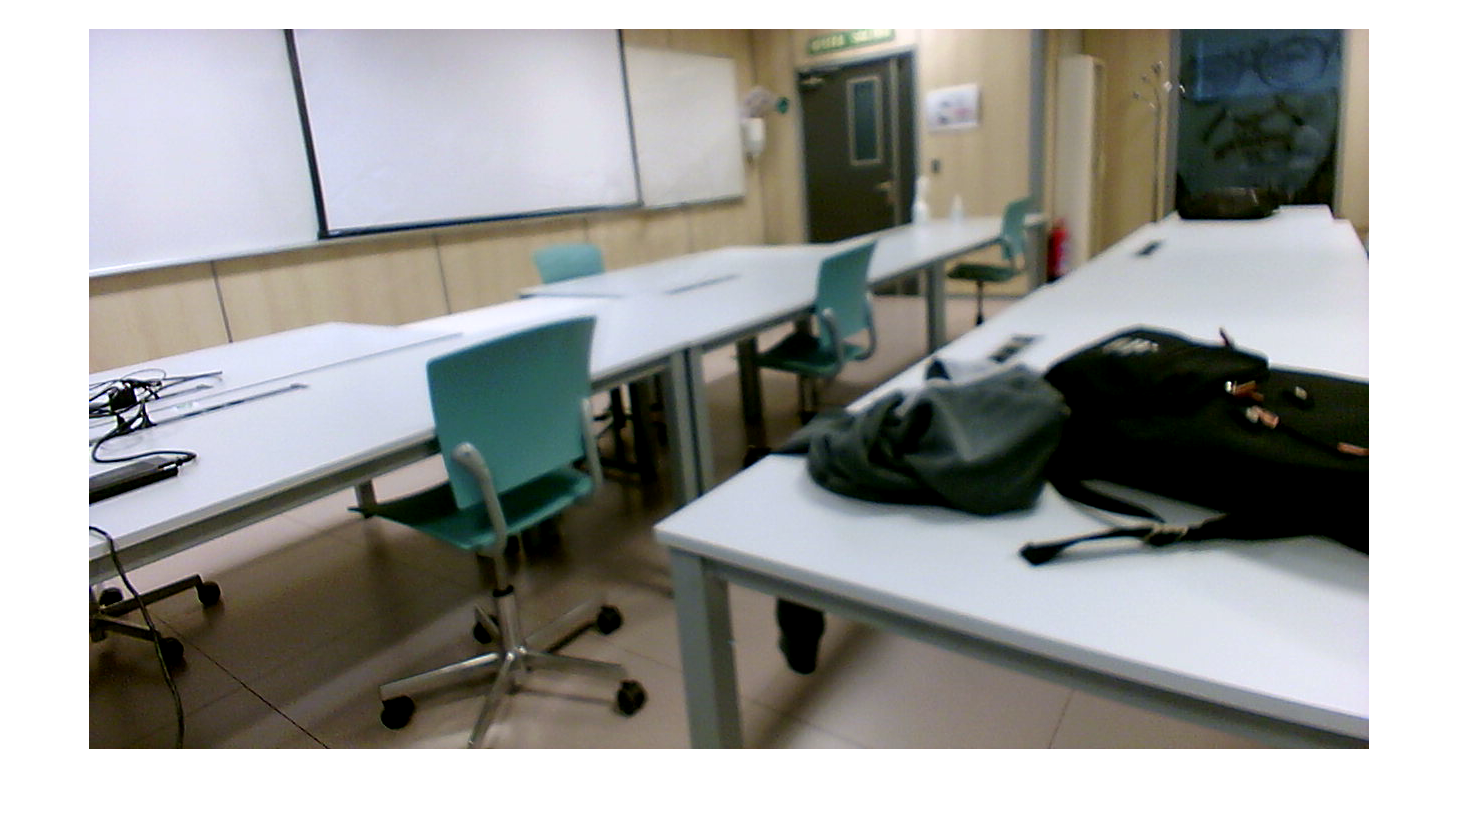

img = snapshot(w);
imshow(img)

[nombre, path] = uiputfile('dibujo.jpg');
fullName = strcat(path, nombre);
imwrite(img, fullName)

Clear the hardware variables when you are no longer using them.

clear w

*Copyright 2018 - 2020 The MathWorks, Inc.*